%% QUADRATIC TIME SERIES FORECASTING TO 2050 WITH ARIMA(5,0,5)
% This script trains on all available data and forecasts to 2050

%% SECTION 1 — Load and Prepare Data
FranceData = readtable("FranceDatawithPop.csv");

% Convert 'Year' to datetime
FranceData.Year = datetime(FranceData.Year, 1, 1);

% Convert to timetable
FranceTT = table2timetable(FranceData, "RowTimes", "Year");

% Use ALL data for training
trainData = FranceTT;

fprintf("✅ Height of training data: %d\n", height(trainData));

✅ Height of training data: 214


fprintf("Training period: %s to %s\n", datestr(trainData.Year(1)), datestr(trainData.Year(end)));

Training period: 01-Jan-1810 to 01-Jan-2023



%% SECTION 2 — Log Transform
fprintf('\n===== LOG TRANSFORMATION =====\n');


===== LOG TRANSFORMATION =====



% Log transform to stabilize variance
yLog = log(trainData.Total + 1);
fprintf('✅ Applied log transformation\n');

✅ Applied log transformation



%% SECTION 3 — Quadratic Detrending
fprintf('\n===== QUADRATIC DETRENDING =====\n');


===== QUADRATIC DETRENDING =====



% Create time variable (numeric years for polynomial fitting)
t = year(trainData.Year);
t_normalized = (t - min(t)) / (max(t) - min(t));  % Normalize to [0,1] for stability

% Fit quadratic polynomial to log-transformed data
quadraticModel = polyfit(t_normalized, yLog, 2);
trendQuadratic = polyval(quadraticModel, t_normalized);

% Compute detrended residuals
yDetrended = yLog - trendQuadratic;

fprintf('✅ Quadratic polynomial coefficients: [%.6f, %.6f, %.6f]\n', quadraticModel);

✅ Quadratic polynomial coefficients: [-6.741469, 11.405749, 1.102564]



%% SECTION 4 — Fit ARIMA(5,0,5) Model
fprintf('\n===== FITTING ARIMA(5,0,5) MODEL =====\n');


===== FITTING ARIMA(5,0,5) MODEL =====



% Fit ARIMA(5,0,5) on detrended data
mdl = arima(5, 0, 5);
bestModel = estimate(mdl, yDetrended, 'Display', 'off');

fprintf('✅ ARIMA(5,0,5) model fitted successfully\n');

✅ ARIMA(5,0,5) model fitted successfully



% Generate fitted values for training data
residuals_train = infer(bestModel, yDetrended);
yDetrended_fitted = yDetrended - residuals_train;

% Add back trend and convert to original scale
yLog_fitted_train = yDetrended_fitted + trendQuadratic;
yPredicted_train = exp(yLog_fitted_train) - 1;

% Calculate training RMSE
trainRMSE = sqrt(mean((yPredicted_train - trainData.Total).^2));
fprintf('Training RMSE: %.4f\n', trainRMSE);

Training RMSE: 14.8955



%% SECTION 5 — Prepare Forecast to 2050
fprintf('\n===== PREPARING FORECAST TO 2050 =====\n');


===== PREPARING FORECAST TO 2050 =====



% Last year in training data
lastYear = year(trainData.Year(end));
targetYear = 2050;

% Calculate how many years to forecast
yearsToForecast = targetYear - lastYear;
fprintf('Forecasting %d years ahead (from %d to %d)\n', yearsToForecast, lastYear, targetYear);

Forecasting 27 years ahead (from 2023 to 2050)



% Create future years
futureYears = (lastYear+1:targetYear)';
futureDates = datetime(futureYears, 1, 1);

%% SECTION 6 — Extend Quadratic Trend to 2050
fprintf('\n===== EXTENDING QUADRATIC TREND =====\n');


===== EXTENDING QUADRATIC TREND =====



% Get original time parameters
t_min = min(t);
t_max = max(t);

% Create future time indices (continuing from training data)
futureIdx = (height(trainData) + 1 : height(trainData) + yearsToForecast)';

% Normalize future time indices
t_future = lastYear + (1:yearsToForecast)';
t_future_normalized = (t_future - t_min) / (t_max - t_min);

% Evaluate quadratic trend at future time points
futureTrendLog = polyval(quadraticModel, t_future_normalized);

fprintf('✅ Quadratic trend extended to 2050\n');

✅ Quadratic trend extended to 2050



%% SECTION 7 — Forecast ARIMA Component
fprintf('\n===== FORECASTING ARIMA COMPONENT =====\n');


===== FORECASTING ARIMA COMPONENT =====



% Forecast the ARIMA model from the end of training data
horizonFuture = yearsToForecast;
[futureArimaFrcst, ~] = forecast(bestModel, horizonFuture, 'Y0', yDetrended);

fprintf('✅ ARIMA forecasts generated\n');

✅ ARIMA forecasts generated



%% SECTION 8 — Combine Trend and ARIMA for Final Predictions
fprintf('\n===== GENERATING FINAL PREDICTIONS =====\n');


===== GENERATING FINAL PREDICTIONS =====



% Combine trend + ARIMA forecast (in log scale)
futureLogPredictions = futureTrendLog + futureArimaFrcst;

% Convert back to original scale
futurePredictions = exp(futureLogPredictions) - 1;

% Display sample predictions
fprintf('\nSample predictions:\n');


Sample predictions:


fprintf('%-10s %-20s\n', 'Year', 'Predicted Emissions');

Year       Predicted Emissions 


fprintf('%s\n', repmat('-', 1, 35));

-----------------------------------


sampleYears = [2024, 2030, 2035, 2040, 2045, 2050];
for i = 1:length(sampleYears)
    yr = sampleYears(i);
    idx = find(futureYears == yr);
    if ~isempty(idx)
        fprintf('%-10d %-20.2f\n', yr, futurePredictions(idx));
    end
end

2024       264.00              
2030       260.77              
2035       252.55              
2040       240.62              
2045       225.99              
2050       209.55              



%% SECTION 9 — Full Visualization (Historical + Forecast)
fprintf('\n===== CREATING VISUALIZATION =====\n');


===== CREATING VISUALIZATION =====


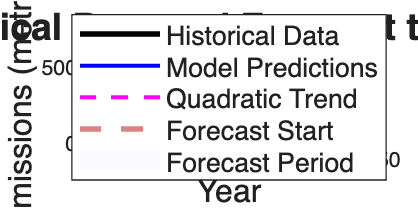


figure('Position', [100 100 1400 700]);

% Combine all predictions (train + future)
allPredictedTime = [trainData.Year; futureDates];
allPredictedTotal = [yPredicted_train; futurePredictions];

% Combine all trend data
trendQuadratic_original = exp(trendQuadratic) - 1;
futureTrend_original = exp(futureTrendLog) - 1;
allTrendTime = [trainData.Year; futureDates];
allTrend = [trendQuadratic_original; futureTrend_original];

% Plot historical actual data
plot(trainData.Year, trainData.Total, 'k-', 'LineWidth', 2, 'DisplayName', 'Historical Data');
hold on;

% Plot all predictions (historical fitted + future forecast)
plot(allPredictedTime, allPredictedTotal, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Model Predictions');

% Plot quadratic trend
plot(allTrendTime, allTrend, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Quadratic Trend');

% Mark forecast start
xline(datetime(lastYear+1, 1, 1), '--', 'Color', [0.8 0.3 0.3], 'LineWidth', 2, ...
    'DisplayName', 'Forecast Start', 'Alpha', 0.7);

% Add shaded region for forecast period
forecastStart = datetime(lastYear+1, 1, 1);
forecastEnd = datetime(2050, 12, 31);
ylims = ylim;
fill([forecastStart forecastEnd forecastEnd forecastStart], ...
     [ylims(1) ylims(1) ylims(2) ylims(2)], ...
     [0.9 0.9 1], 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
     'DisplayName', 'Forecast Period');

xlabel('Year', 'FontSize', 12);
ylabel('CO₂ Emissions (metric tons)', 'FontSize', 12);
title('France CO₂ Emissions: Historical Data and Forecast to 2050 (Quadratic ARIMA(5,0,5))', 'FontSize', 14);
legend('Location', 'best', 'FontSize', 10);
grid on;
hold off;

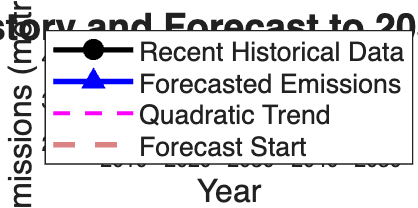


%% SECTION 10 — Zoom in on Recent History and Forecast
figure('Position', [100 100 1200 600]);

% Show last 20 years of actual + all forecast
recentStartYear = lastYear - 20;
recentIdx = trainData.Year >= datetime(recentStartYear, 1, 1);

% Plot recent actual data
recentActualTime = trainData.Year(recentIdx);
recentActualTotal = trainData.Total(recentIdx);
plot(recentActualTime, recentActualTotal, 'ko-', 'LineWidth', 2, 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'DisplayName', 'Recent Historical Data');
hold on;

% Plot forecast
plot(futureDates, futurePredictions, 'b^-', 'LineWidth', 2, 'MarkerSize', 5, ...
    'MarkerFaceColor', 'b', 'DisplayName', 'Forecasted Emissions');

% Plot trend for this period
recentTrendIdx = allTrendTime >= datetime(recentStartYear, 1, 1);
plot(allTrendTime(recentTrendIdx), allTrend(recentTrendIdx), 'm--', 'LineWidth', 1.5, ...
    'DisplayName', 'Quadratic Trend');

% Mark forecast start
xline(datetime(lastYear+1, 1, 1), '--', 'Color', [0.8 0.3 0.3], 'LineWidth', 2, ...
    'DisplayName', 'Forecast Start');

xlabel('Year', 'FontSize', 12);
ylabel('CO₂ Emissions (metric tons)', 'FontSize', 12);
title('Detailed View: Recent History and Forecast to 2050 (Quadratic ARIMA(5,0,5))', 'FontSize', 14);
legend('Location', 'best', 'FontSize', 10);
grid on;
hold off;


%% SECTION 11 — Summary Statistics
fprintf('\n===== FORECAST SUMMARY =====\n');


===== FORECAST SUMMARY =====


fprintf('Model: Quadratic ARIMA(5,0,5)\n');

Model: Quadratic ARIMA(5,0,5)


fprintf('Training RMSE: %.4f\n', trainRMSE);

Training RMSE: 14.8955


fprintf('Last historical year: %d (Emissions: %.2f)\n', lastYear, trainData.Total(end));

Last historical year: 2023 (Emissions: 268.81)


fprintf('Forecast period: %d to %d\n', futureYears(1), futureYears(end));

Forecast period: 2024 to 2050


fprintf('\nKey forecast values:\n');


Key forecast values:


fprintf('  2024: %.2f\n', futurePredictions(futureYears == 2024));

  2024: 264.00


fprintf('  2025: %.2f\n', futurePredictions(futureYears == 2025));

  2025: 263.67


fprintf('  2030: %.2f\n', futurePredictions(futureYears == 2030));

  2030: 260.77


fprintf('  2040: %.2f\n', futurePredictions(futureYears == 2040));

  2040: 240.62


fprintf('  2050: %.2f\n', futurePredictions(end));

  2050: 209.55


fprintf('\nProjected change from %d to 2050: %.2f (%.1f%%)\n', ...
    lastYear, futurePredictions(end) - trainData.Total(end), ...
    100 * (futurePredictions(end) - trainData.Total(end)) / trainData.Total(end));


Projected change from 2023 to 2050: -59.25 (-22.0%)



%% SECTION 12 — Save Results
% Create forecast table
forecastTable = table(futureDates, futureYears, futurePredictions, ...
    'VariableNames', {'Date', 'Year', 'PredictedEmissions'});

save('QuadraticForecast_to_2050.mat', 'forecastTable', 'futurePredictions', 'futureDates', ...
     'futureYears', 'bestModel', 'quadraticModel', 'trainData', 'yPredicted_train');
fprintf('\n✅ Forecast results saved to QuadraticForecast_to_2050.mat\n');


✅ Forecast results saved to QuadraticForecast_to_2050.mat



% Export to CSV
writetable(forecastTable, 'QuadraticForecast_to_2050.csv');
fprintf('✅ Forecast table exported to QuadraticForecast_to_2050.csv\n');

✅ Forecast table exported to QuadraticForecast_to_2050.csv
